# Markov chain Monte Carlo methods

Markov chain Monte Carlo (MCMC) methods are methods that can sample from a probability density when only an expression for an unnormalized density is available.

We will demonstrate the Metropolis MCMC method for the unnormalized density


$$|\sin(2\pi x)| x - x^2 + x$$


defined for $0<x<1$. The density is zero outside this interval.

The proposal distribution is $N(y|x,\;0.01)$.

nsamp = 10000000;              % number of samples
c = zeros(nsamp,1);            % array for storing the samples
numacc = 0;                    % number of accepted candidates
x = 0.2;                       % initial state

% MCMC sampling
for k = 1:nsamp
  y = x + 0.1*randn;           % candidate from proposal distribution
  a = min(1, qfun(y)/qfun(x)); % acceptance probability
  t = rand;
  if t < a
    numacc = numacc + 1;       % count accepted candidate
    x = y;                     % new state is accepted state
  else
    x = x;                     % new state is same as current state
  end
  c(k) = x;                    % store the new state
end

fprintf('Fraction of accepted candidates: %f\n', numacc/nsamp);

Fraction of accepted candidates: 0.824537


Plot a histogram of the samples. Overlay a plot of the unnormalized density scaled the same way (by matching the peak of the density with the peak of the histogram).

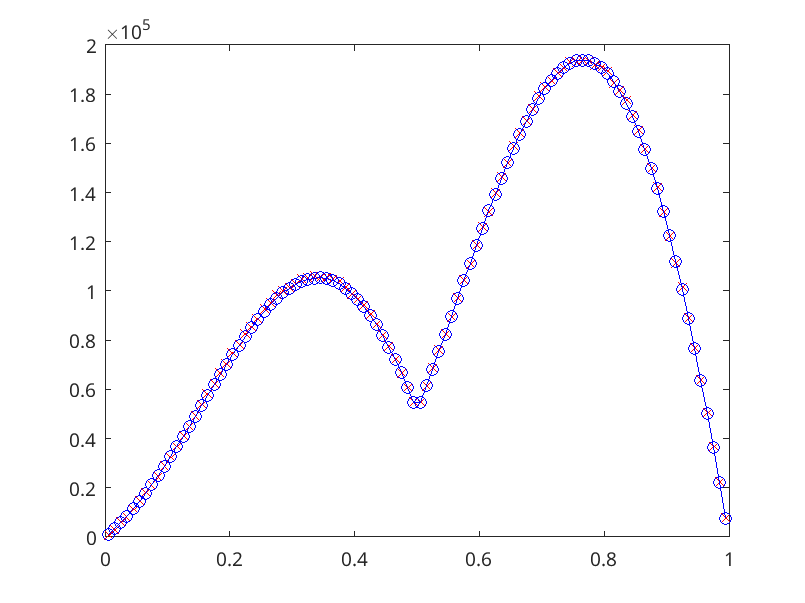

bw = 1/100;                    % histogram bin widths
x = bw/2:bw:1-bw/2;            % histogram centers
h = hist(c, x);                % count number of states in each bin
clf
plot(x, h, 'rx');              % plot histogram
hold on
fun = @(x) abs(sin(2*pi*x)).*x - x.^2 + x;
y = fun(x);
plot(x,y/max(y)*max(h),'bo-'); % plot normalized original distribution

Define the unnormalized density function.

function p = qfun(x)
if x < 0 || x > 1
  p = 0;
else
  p = abs(sin(2*pi*x))*x - x^2 + x;
end
end

### Taking it further

Hypothesize what happens when you use a different value of the variance in the proposal distribution. Check your hypothesis by running the code with different values of the proposal distribution variance.

The above code is just a barebones example of generating MCMC samples. Augment this code to avoid the effect of the initial state (i.e., discard initial samples) and avoid correlations between samples (i.e., only keep every $k$th sample, where $k$ is some number). How do these improvements help the efficiency of the sampling, particularly when only a rough estimate of the distribution is desired?

Implement MCMC sampling for 2 dimensions or more dimensions. 